# Multirate Signal Processing

## Multirate Signal Processing

Discrete-time systems with different sampling rates at various parts of the system are called *multirate systems*.

The fundamental operations for changing the sampling rate are:

- decimation 

- interpolation

### Sampling rate conversion

Conceptually, the sampling rate conversion process can be regarded as a two-step operation:

- the discrete-time signal is reconstructed into a continuous-time signal  

- the signal is resampled at a different sampling rate  

In practice, the conversion is implemented using discrete-time signal processing without actual reconstruction of any continuous-time signal.

The term* resampling *is used to refer to the process of changing the *sampling rate* of a discrete-time signal without reconstructing the equavilent continous-time signal. 

There are three resampling operations:

- $T_0 =\mathrm{DT}$, downsampling i.e., decreasing the sampling rate by an integer factor $D$

- $T_0 =\frac{T}{I}$, upsampling i.e., increasing the sampling rate by an integer factor $I$

- $T_0 =T\left(\frac{D}{I}\right)$, changing the sampling rate by non-integer factor 

where $T$ is the sampling rate of the original signal, $T_0$ is the new sampling rate, and $D$ and $I$ are integers.

### Downsampling

## [»] Problem 12.21: Resampling downsampled sequences

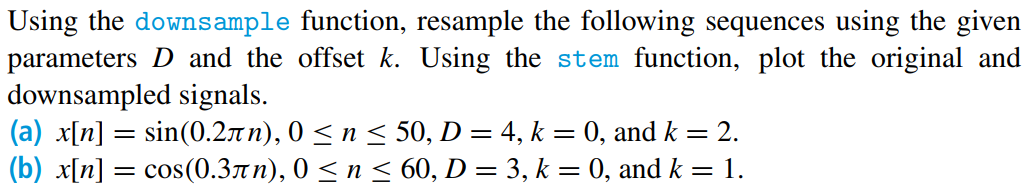

## [»] Problem 12.22: Resample decimated sequences

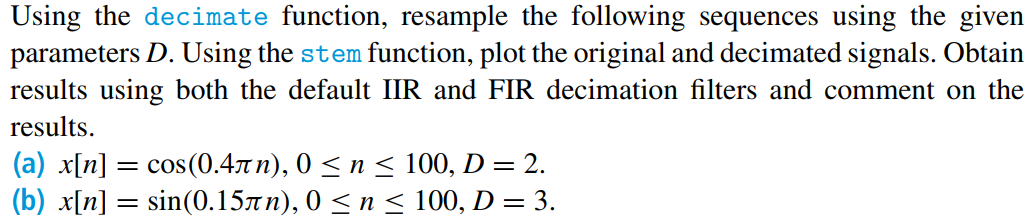

## [✔] Problem 12.26: Interpolation using MATLAB's interp function

clear variables;

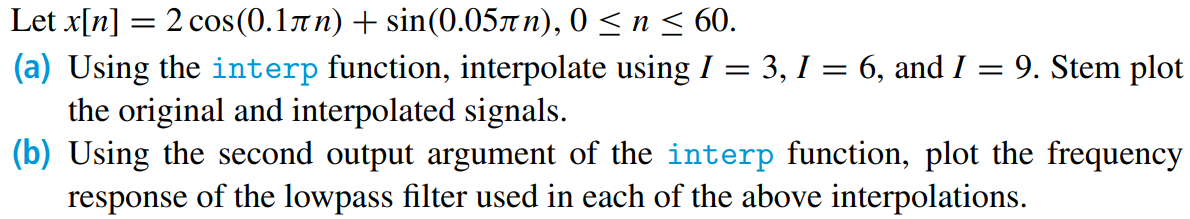

### a) Interpolate signal using MATLAB's interp function

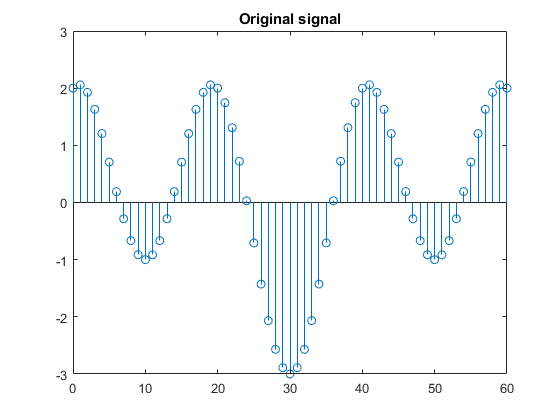

n = 0:60;
x = 2*cos(0.1*pi*n) + sin(0.05*pi*n);

stem(n, x)
title('Original signal')

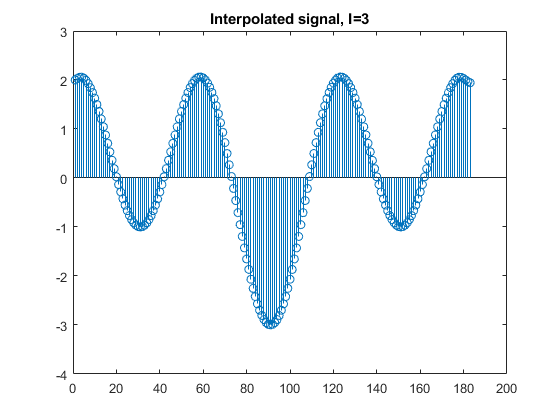

stem(interp(x, 3))
title('Interpolated signal, I=3')

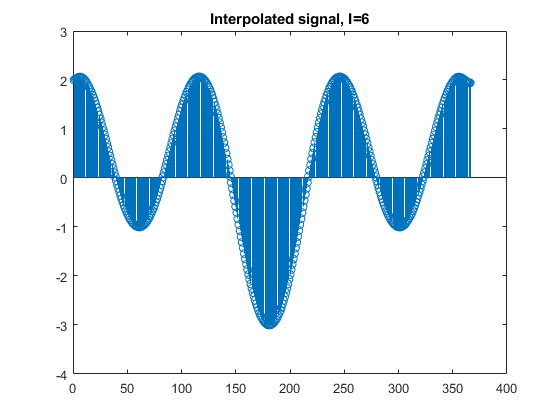

stem(interp(x, 6))
title('Interpolated signal, I=6')

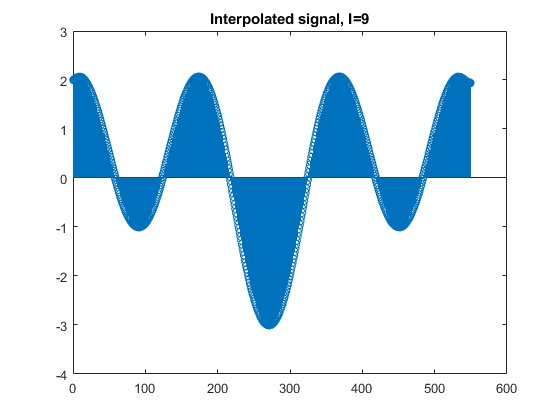

stem(interp(x, 9))
title('Interpolated signal, I=9')

### b) Plot the frequency response of the lowpass filter

`[`[`y`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94488)`,`[`b`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94527)`] = interp(`[`x`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94346)`,`[`r`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94376)`,`[`n`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94406)`,`[`cutoff`](https://se.mathworks.com/help/signal/ref/interp.html#d117e94449)`)` returns a vector, b, with the filter coefficients used for the interpolation.

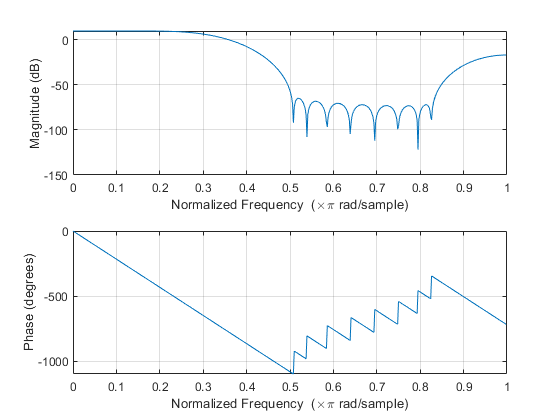

[y, b] = interp(x, 3);
freqz(b, 1)

## [»] Problem 12.19: Compare spectrum of a downsampled signal with the original

clear variables;

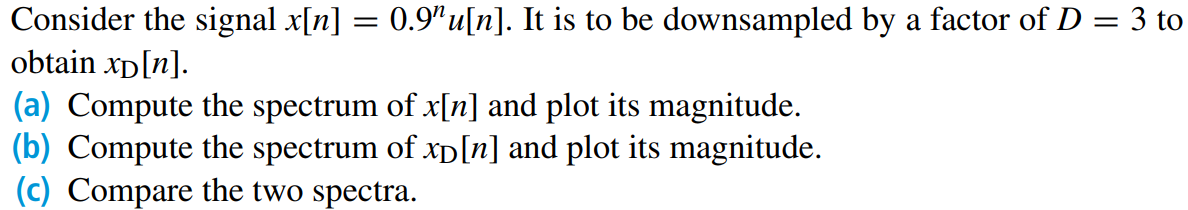

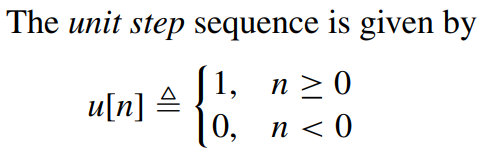

### a) Compute the spectrum of the original signal and plot its magnitude

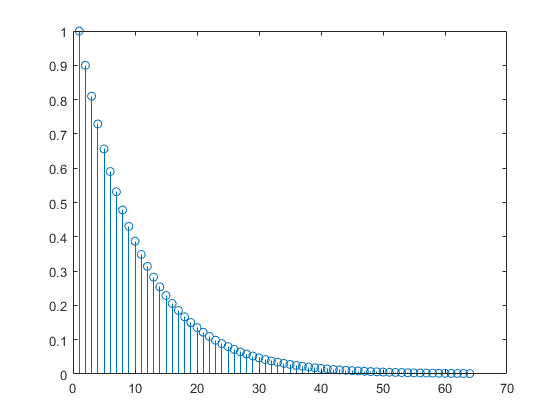

N = 64;
n = 0:N-1;
x = 0.9.^n;
% x = exp(-n);
stem(x)

[?] How do you compute the spectrum of the signal?

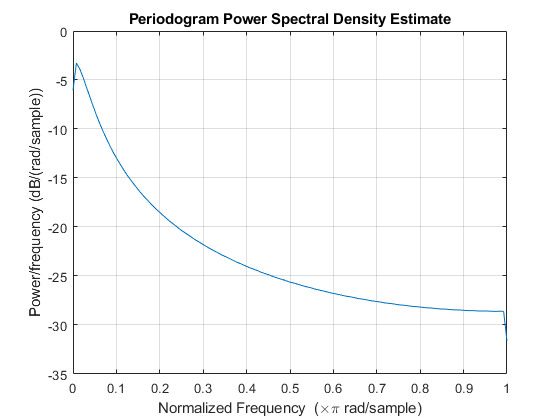

periodogram(x)

### a) Compute the spectrum of the signal and plot its magnitude

### b) Compute the spectrum of the downsampled signal and plot its magnitude

### c) Compare the two spectra

## ADSI Problem 8.1: Upsampling with linear interpolation

clear variables;

Consider a signal given by:

        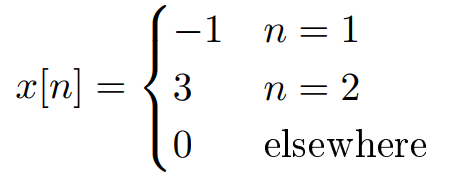

N = 10;
n = 1:N;
x = zeros(N,1);
x(1) = -1;
x(2) = 3;

### 1. Upsample the signal using *I *= 4 and the linear interpolation kernel given by Eq. 12.48.  

        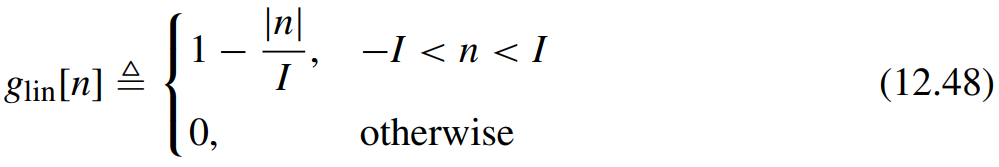

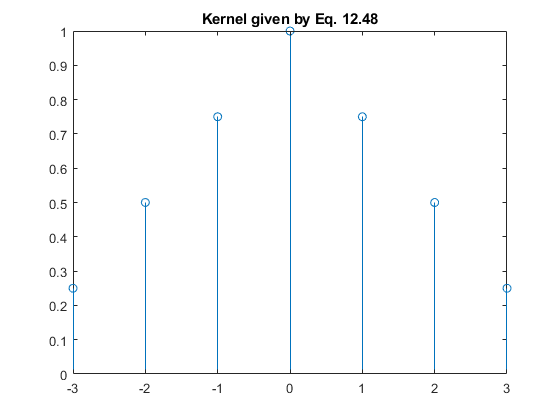

I = 4;
gn = -I+1:1:I-1;
g = 1 - abs(gn)/I;  % g = triang(I*2-1)

stem(gn, g);
title('Kernel given by Eq. 12.48')

x_upsampled = conv(x, g);

### 2. Sketch the signal before and after the upsampling and interpolation.  

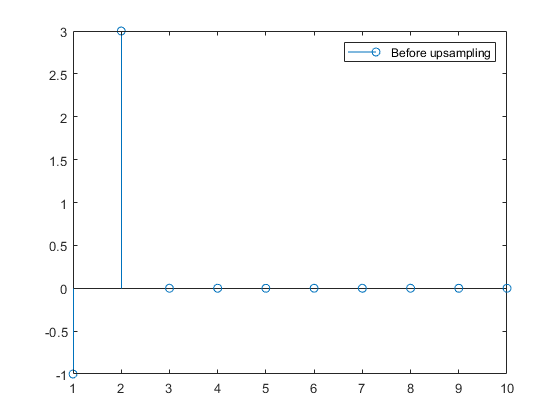

stem(n, x)
legend('Before upsampling')

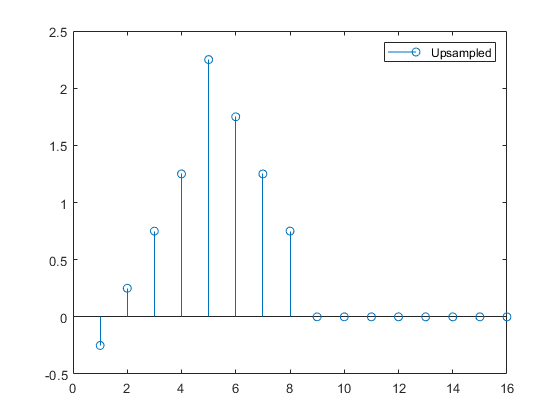

stem(x_upsampled)
legend('Upsampled')